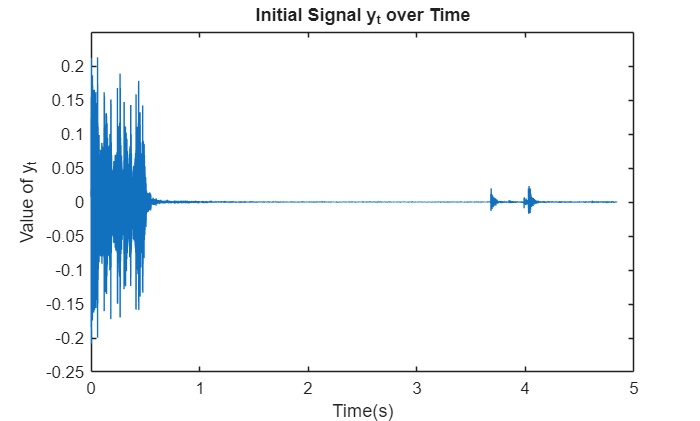


load short_modem_rx.mat

% The received signal includes a bunch of samples from before the
% transmission started so we need discard these samples that occurred before
% the transmission started. 

start_idx = find_start_of_signal(y_r,x_sync);
% start_idx now contains the location in y_r where x_sync begins
% we need to offset by the length of x_sync to only include the signal
% we are interested in
y_t = y_r(start_idx+length(x_sync):end); % y_t is the signal which starts at the beginning of the transmission


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%  Put your decoder code here
t = (0:length(y_t)-1)'/Fs; 
plot(t, y_t)
title("Initial Signal y_t over Time")
xlabel("Time(s)")
ylabel("Value of y_t")

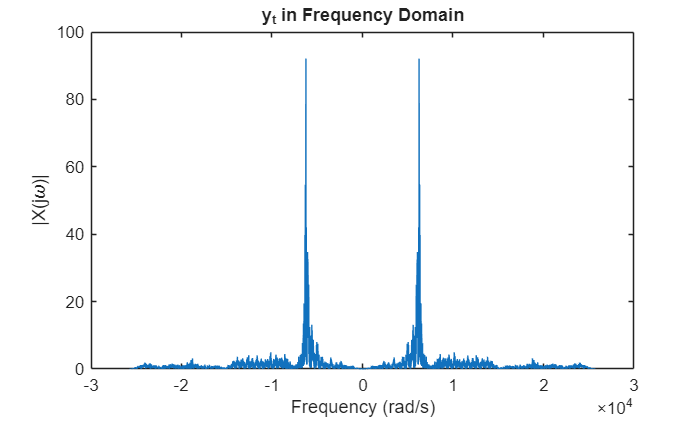


[f, X] = make_frequency_domain_plot(Fs, y_t, "y_t");

soundsc(y_t, Fs)

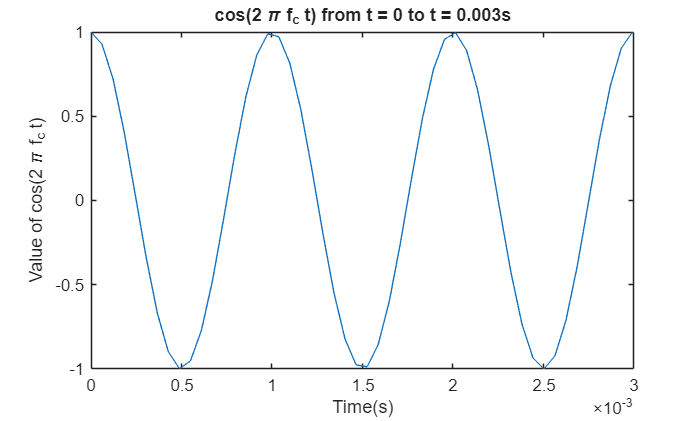


%% 
t_special = (0:length(y_t)-1)'/(Fs*2); 
cosinewave = cos(2*pi*f_c*t);
cosinewave_special = cos(2*pi*f_c*t_special);
plot(t_special(1:50), cosinewave_special(1:50))
title("cos(2 \pi f_c t) from t = 0 to t = 0.003s")
xlabel("Time(s)")
ylabel("Value of cos(2 \pi f_c t)")

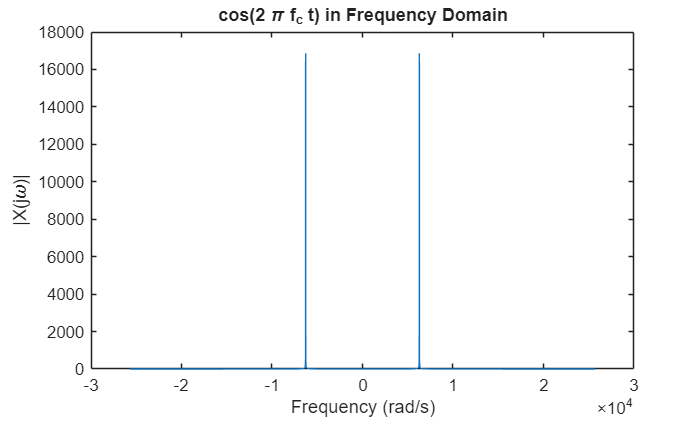



[f, X] = make_frequency_domain_plot(Fs, cosinewave, "cos(2 \pi f_c t)");

soundsc(cosinewave(1:4000), Fs)

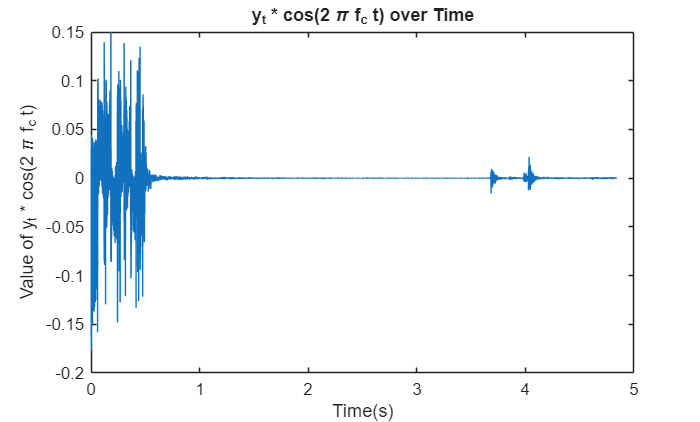

%% 

x_d = y_t .* cosinewave; 
plot(t, x_d)
title("y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Value of y_t * cos(2 \pi f_c t)")

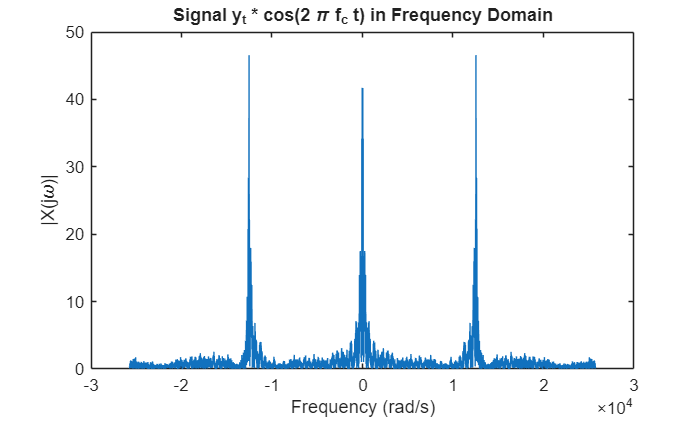

[f, X] = make_frequency_domain_plot(Fs, x_d, "Signal y_t * cos(2 \pi f_c t)");

soundsc(x_d, Fs)

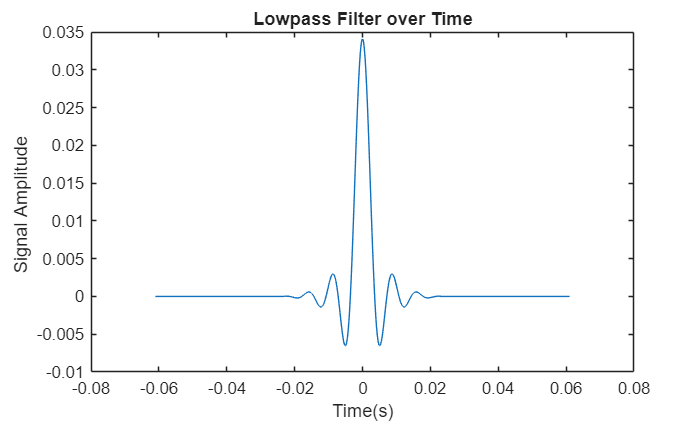

%% 

x_d_fil = lowpass(x_d,100,Fs,'Steepness',0.99);
%% 

lowpass_filter = lowpass([zeros([500 1]) ; 1 ; zeros([500 1])],100,Fs,'Steepness',0.99);
t_sp = (0:length(lowpass_filter)-1)'/Fs - ((length(lowpass_filter)-1)/Fs)/2;
plot(t_sp, lowpass_filter)
title("Lowpass Filter over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude ")

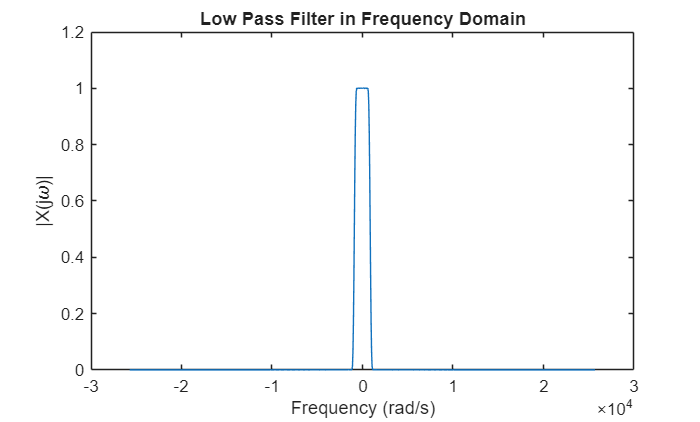




[f, X] = make_frequency_domain_plot(Fs, lowpass_filter, "Low Pass Filter");

soundsc(x_d_fil, Fs)

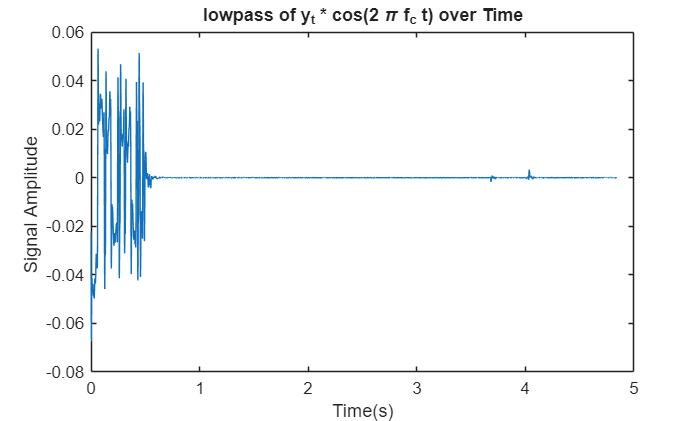

%% 
t_special2 = (1:1:length(x_d_fil))/Fs;
plot(t_special2, x_d_fil)
title("lowpass of y_t * cos(2 \pi f_c t) over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude ")

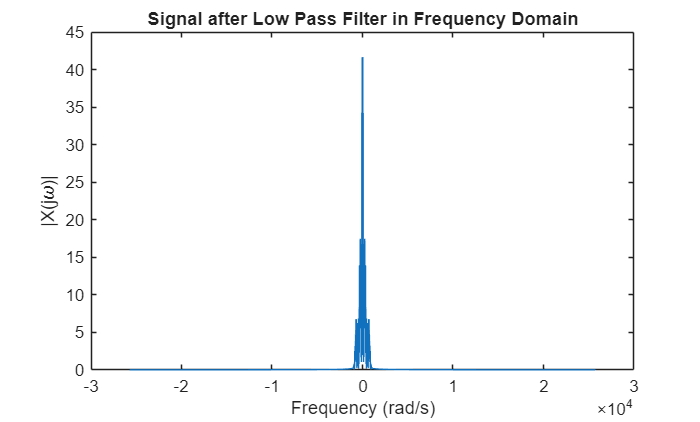

[f, X] = make_frequency_domain_plot(Fs, x_d_fil, "Signal after Low Pass Filter");

soundsc(20.*x_d_fil, Fs)


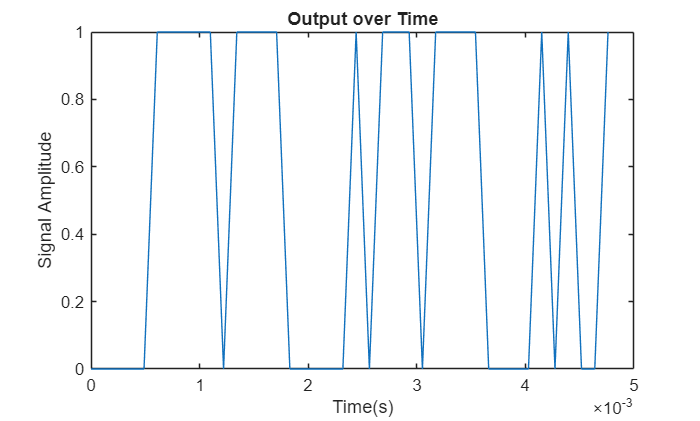

per = 100; 

mid_idx = (per/2):per:length(x_d_fil); % middle of each bit
s_vals = x_d_fil(mid_idx); % sampled values/bit
d_bit = s_vals > 0; % pos is 1 neg is 0

tot_bits = msg_length*8; % total bits

x_d = d_bit(1:tot_bits); % cut off extra bits at the end
t = (0:length(x_d)-1)'/Fs;
plot(t, x_d)
title("Output over Time")
xlabel("Time(s)")
ylabel("Signal Amplitude")

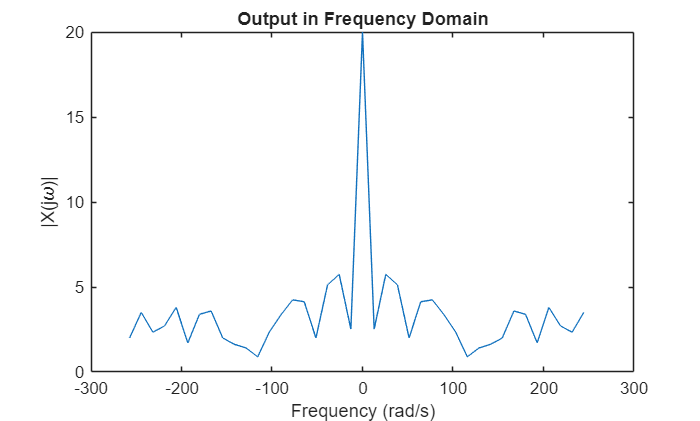


[f, X] = make_frequency_domain_plot(Fs/100, x_d, "Output");

%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

soundsc(x_d*1.00, Fs)
% convert to a string assuming that x_d is a vector of 1s and 0s
% representing the decoded bits.
BitsToString(x_d)

ans = 'Hello'


function [f, X] = make_frequency_domain_plot(Fs, x, Algorithm)
    [X, f] = plot_ft_rad(x, Fs);
    title(Algorithm + ' in Frequency Domain')
end